# Week 4 Demo

## More on Script Functions

Last week, we got to take a look at script functions, and you got to make a (somewhat simple) code which computed $y(x) = x^2$.  In practice, such a function would be coded as an anonymous function.  In scripts, you can do a lot more than compute values.  You will see in today's worksheet that the capabilities of script functions include but are not limited to: computing outputs, creating plots, generating functions, manipulating variables, etc.  

To start, let's create a (normal) script.  We will call it plot_2_functions.  As inputs, it will take functions $f(x)$ and $g(x)$ as anonymous functions, and it will take interval endpoints $x_0$ and $x_1$.  The code will create an interval $x\in[x_0,x_1]$ using linspace and then plot $f$ and $g$ over the interval.  The funciton will output vectors containing values for $x$, $f(x)$ and $g(x)$.  

Once created, let's go ahead and test it out.  Let's let $f(x) = x$, $g(x) = \sin(x)$, $x_0=0$, and $x_1 = 2\pi$.  

f = @(x) x;
g = @(x) sin(x);
x0 = 0

x0 = 0

x1 = 2*pi

x1 = 6.2832

[x, fx, gx] = plot_2_function(f,g,x0,x1)

x =          0    0.0635    0.1269    0.1904    0.2539    0.3173    0.3808    0.4443    0.5077    0.5712    0.6347    0.6981    0.7616    0.8251    0.8885    0.9520    1.0155    1.0789    1.1424    1.2059    1.2693    1.3328    1.3963    1.4597    1.5232    1.5867    1.6501    1.7136    1.7771    1.8405    1.9040    1.9675    2.0309    2.0944    2.1579    2.2213    2.2848    2.3483    2.4117    2.4752    2.5387    2.6021    2.6656    2.7291    2.7925    2.8560    2.9195    2.9829    3.0464    3.1099


fx =          0    0.0635    0.1269    0.1904    0.2539    0.3173    0.3808    0.4443    0.5077    0.5712    0.6347    0.6981    0.7616    0.8251    0.8885    0.9520    1.0155    1.0789    1.1424    1.2059    1.2693    1.3328    1.3963    1.4597    1.5232    1.5867    1.6501    1.7136    1.7771    1.8405    1.9040    1.9675    2.0309    2.0944    2.1579    2.2213    2.2848    2.3483    2.4117    2.4752    2.5387    2.6021    2.6656    2.7291    2.7925    2.8560    2.9195    2.9829    3.0464    3.1099


gx =          0    0.0634    0.1266    0.1893    0.2511    0.3120    0.3717    0.4298    0.4862    0.5406    0.5929    0.6428    0.6901    0.7346    0.7761    0.8146    0.8497    0.8815    0.9096    0.9341    0.9549    0.9718    0.9848    0.9938    0.9989    0.9999    0.9969    0.9898    0.9788    0.9638    0.9450    0.9224    0.8960    0.8660    0.8326    0.7958    0.7557    0.7127    0.6668    0.6182    0.5671    0.5137    0.4582    0.4009    0.3420    0.2817    0.2203    0.1580    0.0951    0.0317


Notice that we created a figure and plotted using the script function!  Now that we have the figure, we can label axes and create a title as usual:

xlabel ('x')
title ('Plots of x and sin(x)')

What if we want to also plot $f(x)g(x)$ and $f(x)/g(x)$ on this figure?  We can do so.  Let's also add a legend.

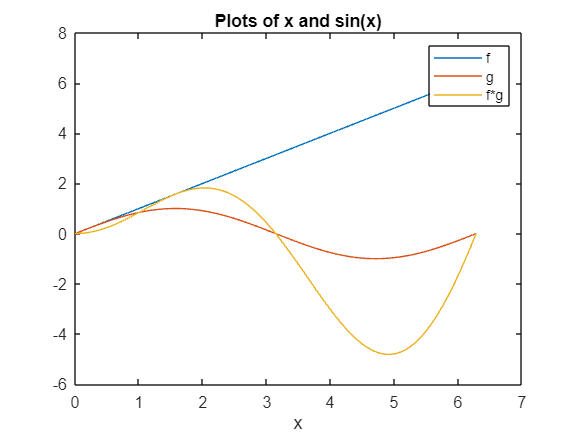

hold on
fg = fx.*gx;
f_g = fx./gx;
plot(x, fg)
% hold on
% plot(x, f_g)
legend('f','g','f*g')

## For Loops

For loops are used heavily in coding.  There are many instances where one wants to repeat the exact same process multiple times.  The "naive" way to code in this case is to copy and paste the same lines of code over and over.  This is fine for when you only need to do something a couple of times, but what happens when you need to do it 1000 times?

The structure of a for-loop is the following:

for i = 1:number of iterations:

    (all relevant code goes here)

end

Let's see some examples.  Suppose we want to compute $\sum_{i=0}^N i^2$, for some large value of $N$.  We can use a for loop for this:

result = 0;
N = 1000; % you could put anything for N to make it go to that number.
for i = 0:N
    result = result + i^2
end 

result = 0

result = 1

result = 5

result = 14

result = 30

result = 55

result = 91

result = 140

result = 204

result = 285

result = 385

result = 506

result = 650

result = 819

result = 1015

result = 1240

result = 1496

result = 1785

result = 2109

result = 2470

result = 2870

result = 3311

result = 3795

result = 4324

result = 4900

result = 5525

result = 6201

result = 6930

result = 7714

result = 8555

result = 9455

result = 10416

result = 11440

result = 12529

result = 13685

result = 14910

result = 16206

result = 17575

result = 19019

result = 20540

result = 22140

result = 23821

result = 25585

result = 27434

result = 29370

result = 31395

result = 33511

result = 35720

result = 38024

result = 40425

result = 42925

result = 45526

result = 48230

result = 51039

result = 53955

result = 56980

result = 60116

result = 63365

result = 66729

result = 70210

result = 73810

result = 77531

result = 81375

result = 85344

result = 89440

result = 93665

result = 98021

result = 102510

result = 107134

result = 111895

result = 116795

result = 121836

result = 127020

result = 132349

result = 137825

result = 143450

result = 149226

result = 155155

result = 161239

result = 167480

result = 173880

result = 180441

result = 187165

result = 194054

result = 201110

result = 208335

result = 215731

result = 223300

result = 231044

result = 238965

result = 247065

result = 255346

result = 263810

result = 272459

result = 281295

result = 290320

result = 299536

result = 308945

result = 318549

result = 328350

result = 338350

result = 348551

result = 358955

result = 369564

result = 380380

result = 391405

result = 402641

result = 414090

result = 425754

result = 437635

result = 449735

result = 462056

result = 474600

result = 487369

result = 500365

result = 513590

result = 527046

result = 540735

result = 554659

result = 568820

result = 583220

result = 597861

result = 612745

result = 627874

result = 643250

result = 658875

result = 674751

result = 690880

result = 707264

result = 723905

result = 740805

result = 757966

result = 775390

result = 793079

result = 811035

result = 829260

result = 847756

result = 866525

result = 885569

result = 904890

result = 924490

result = 944371

result = 964535

result = 984984

result = 1005720

result = 1026745

result = 1048061

result = 1069670

result = 1091574

result = 1113775

result = 1136275

result = 1159076

result = 1182180

result = 1205589

result = 1229305

result = 1253330

result = 1277666

result = 1302315

result = 1327279

result = 1352560

result = 1378160

result = 1404081

result = 1430325

result = 1456894

result = 1483790

result = 1511015

result = 1538571

result = 1566460

result = 1594684

result = 1623245

result = 1652145

result = 1681386

result = 1710970

result = 1740899

result = 1771175

result = 1801800

result = 1832776

result = 1864105

result = 1895789

result = 1927830

result = 1960230

result = 1992991

result = 2026115

result = 2059604

result = 2093460

result = 2127685

result = 2162281

result = 2197250

result = 2232594

result = 2268315

result = 2304415

result = 2340896

result = 2377760

result = 2415009

result = 2452645

result = 2490670

result = 2529086

result = 2567895

result = 2607099

result = 2646700

result = 2686700

result = 2727101

result = 2767905

result = 2809114

result = 2850730

result = 2892755

result = 2935191

result = 2978040

result = 3021304

result = 3064985

result = 3109085

result = 3153606

result = 3198550

result = 3243919

result = 3289715

result = 3335940

result = 3382596

result = 3429685

result = 3477209

result = 3525170

result = 3573570

result = 3622411

result = 3671695

result = 3721424

result = 3771600

result = 3822225

result = 3873301

result = 3924830

result = 3976814

result = 4029255

result = 4082155

result = 4135516

result = 4189340

result = 4243629

result = 4298385

result = 4353610

result = 4409306

result = 4465475

result = 4522119

result = 4579240

result = 4636840

result = 4694921

result = 4753485

result = 4812534

result = 4872070

result = 4932095

result = 4992611

result = 5053620

result = 5115124

result = 5177125

result = 5239625

result = 5302626

result = 5366130

result = 5430139

result = 5494655

result = 5559680

result = 5625216

result = 5691265

result = 5757829

result = 5824910

result = 5892510

result = 5960631

result = 6029275

result = 6098444

result = 6168140

result = 6238365

result = 6309121

result = 6380410

result = 6452234

result = 6524595

result = 6597495

result = 6670936

result = 6744920

result = 6819449

result = 6894525

result = 6970150

result = 7046326

result = 7123055

result = 7200339

result = 7278180

result = 7356580

result = 7435541

result = 7515065

result = 7595154

result = 7675810

result = 7757035

result = 7838831

result = 7921200

result = 8004144

result = 8087665

result = 8171765

result = 8256446

result = 8341710

result = 8427559

result = 8513995

result = 8601020

result = 8688636

result = 8776845

result = 8865649

result = 8955050

result = 9045050

result = 9135651

result = 9226855

result = 9318664

result = 9411080

result = 9504105

result = 9597741

result = 9691990

result = 9786854

result = 9882335

result = 9978435

result = 10075156

result = 10172500

result = 10270469

result = 10369065

result = 10468290

result = 10568146

result = 10668635

result = 10769759

result = 10871520

result = 10973920

result = 11076961

result = 11180645

result = 11284974

result = 11389950

result = 11495575

result = 11601851

result = 11708780

result = 11816364

result = 11924605

result = 12033505

result = 12143066

result = 12253290

result = 12364179

result = 12475735

result = 12587960

result = 12700856

result = 12814425

result = 12928669

result = 13043590

result = 13159190

result = 13275471

result = 13392435

result = 13510084

result = 13628420

result = 13747445

result = 13867161

result = 13987570

result = 14108674

result = 14230475

result = 14352975

result = 14476176

result = 14600080

result = 14724689

result = 14850005

result = 14976030

result = 15102766

result = 15230215

result = 15358379

result = 15487260

result = 15616860

result = 15747181

result = 15878225

result = 16009994

result = 16142490

result = 16275715

result = 16409671

result = 16544360

result = 16679784

result = 16815945

result = 16952845

result = 17090486

result = 17228870

result = 17367999

result = 17507875

result = 17648500

result = 17789876

result = 17932005

result = 18074889

result = 18218530

result = 18362930

result = 18508091

result = 18654015

result = 18800704

result = 18948160

result = 19096385

result = 19245381

result = 19395150

result = 19545694

result = 19697015

result = 19849115

result = 20001996

result = 20155660

result = 20310109

result = 20465345

result = 20621370

result = 20778186

result = 20935795

result = 21094199

result = 21253400

result = 21413400

result = 21574201

result = 21735805

result = 21898214

result = 22061430

result = 22225455

result = 22390291

result = 22555940

result = 22722404

result = 22889685

result = 23057785

result = 23226706

result = 23396450

result = 23567019

result = 23738415

result = 23910640

result = 24083696

result = 24257585

result = 24432309

result = 24607870

result = 24784270

result = 24961511

result = 25139595

result = 25318524

result = 25498300

result = 25678925

result = 25860401

result = 26042730

result = 26225914

result = 26409955

result = 26594855

result = 26780616

result = 26967240

result = 27154729

result = 27343085

result = 27532310

result = 27722406

result = 27913375

result = 28105219

result = 28297940

result = 28491540

result = 28686021

result = 28881385

result = 29077634

result = 29274770

result = 29472795

result = 29671711

result = 29871520

result = 30072224

result = 30273825

result = 30476325

result = 30679726

result = 30884030

result = 31089239

result = 31295355

result = 31502380

result = 31710316

result = 31919165

result = 32128929

result = 32339610

result = 32551210

result = 32763731

result = 32977175

result = 33191544

result = 33406840

result = 33623065

result = 33840221

result = 34058310

result = 34277334

result = 34497295

result = 34718195

result = 34940036

result = 35162820

result = 35386549

result = 35611225

result = 35836850

result = 36063426

result = 36290955

result = 36519439

result = 36748880

result = 36979280

result = 37210641

result = 37442965

result = 37676254

result = 37910510

result = 38145735

result = 38381931

result = 38619100

result = 38857244

result = 39096365

result = 39336465

result = 39577546

result = 39819610

result = 40062659

result = 40306695

result = 40551720

result = 40797736

result = 41044745

result = 41292749

result = 41541750

result = 41791750

result = 42042751

result = 42294755

result = 42547764

result = 42801780

result = 43056805

result = 43312841

result = 43569890

result = 43827954

result = 44087035

result = 44347135

result = 44608256

result = 44870400

result = 45133569

result = 45397765

result = 45662990

result = 45929246

result = 46196535

result = 46464859

result = 46734220

result = 47004620

result = 47276061

result = 47548545

result = 47822074

result = 48096650

result = 48372275

result = 48648951

result = 48926680

result = 49205464

result = 49485305

result = 49766205

result = 50048166

result = 50331190

result = 50615279

result = 50900435

result = 51186660

result = 51473956

result = 51762325

result = 52051769

result = 52342290

result = 52633890

result = 52926571

result = 53220335

result = 53515184

result = 53811120

result = 54108145

result = 54406261

result = 54705470

result = 55005774

result = 55307175

result = 55609675

result = 55913276

result = 56217980

result = 56523789

result = 56830705

result = 57138730

result = 57447866

result = 57758115

result = 58069479

result = 58381960

result = 58695560

result = 59010281

result = 59326125

result = 59643094

result = 59961190

result = 60280415

result = 60600771

result = 60922260

result = 61244884

result = 61568645

result = 61893545

result = 62219586

result = 62546770

result = 62875099

result = 63204575

result = 63535200

result = 63866976

result = 64199905

result = 64533989

result = 64869230

result = 65205630

result = 65543191

result = 65881915

result = 66221804

result = 66562860

result = 66905085

result = 67248481

result = 67593050

result = 67938794

result = 68285715

result = 68633815

result = 68983096

result = 69333560

result = 69685209

result = 70038045

result = 70392070

result = 70747286

result = 71103695

result = 71461299

result = 71820100

result = 72180100

result = 72541301

result = 72903705

result = 73267314

result = 73632130

result = 73998155

result = 74365391

result = 74733840

result = 75103504

result = 75474385

result = 75846485

result = 76219806

result = 76594350

result = 76970119

result = 77347115

result = 77725340

result = 78104796

result = 78485485

result = 78867409

result = 79250570

result = 79634970

result = 80020611

result = 80407495

result = 80795624

result = 81185000

result = 81575625

result = 81967501

result = 82360630

result = 82755014

result = 83150655

result = 83547555

result = 83945716

result = 84345140

result = 84745829

result = 85147785

result = 85551010

result = 85955506

result = 86361275

result = 86768319

result = 87176640

result = 87586240

result = 87997121

result = 88409285

result = 88822734

result = 89237470

result = 89653495

result = 90070811

result = 90489420

result = 90909324

result = 91330525

result = 91753025

result = 92176826

result = 92601930

result = 93028339

result = 93456055

result = 93885080

result = 94315416

result = 94747065

result = 95180029

result = 95614310

result = 96049910

result = 96486831

result = 96925075

result = 97364644

result = 97805540

result = 98247765

result = 98691321

result = 99136210

result = 99582434

result = 100029995

result = 100478895

result = 100929136

result = 101380720

result = 101833649

result = 102287925

result = 102743550

result = 103200526

result = 103658855

result = 104118539

result = 104579580

result = 105041980

result = 105505741

result = 105970865

result = 106437354

result = 106905210

result = 107374435

result = 107845031

result = 108317000

result = 108790344

result = 109265065

result = 109741165

result = 110218646

result = 110697510

result = 111177759

result = 111659395

result = 112142420

result = 112626836

result = 113112645

result = 113599849

result = 114088450

result = 114578450

result = 115069851

result = 115562655

result = 116056864

result = 116552480

result = 117049505

result = 117547941

result = 118047790

result = 118549054

result = 119051735

result = 119555835

result = 120061356

result = 120568300

result = 121076669

result = 121586465

result = 122097690

result = 122610346

result = 123124435

result = 123639959

result = 124156920

result = 124675320

result = 125195161

result = 125716445

result = 126239174

result = 126763350

result = 127288975

result = 127816051

result = 128344580

result = 128874564

result = 129406005

result = 129938905

result = 130473266

result = 131009090

result = 131546379

result = 132085135

result = 132625360

result = 133167056

result = 133710225

result = 134254869

result = 134800990

result = 135348590

result = 135897671

result = 136448235

result = 137000284

result = 137553820

result = 138108845

result = 138665361

result = 139223370

result = 139782874

result = 140343875

result = 140906375

result = 141470376

result = 142035880

result = 142602889

result = 143171405

result = 143741430

result = 144312966

result = 144886015

result = 145460579

result = 146036660

result = 146614260

result = 147193381

result = 147774025

result = 148356194

result = 148939890

result = 149525115

result = 150111871

result = 150700160

result = 151289984

result = 151881345

result = 152474245

result = 153068686

result = 153664670

result = 154262199

result = 154861275

result = 155461900

result = 156064076

result = 156667805

result = 157273089

result = 157879930

result = 158488330

result = 159098291

result = 159709815

result = 160322904

result = 160937560

result = 161553785

result = 162171581

result = 162790950

result = 163411894

result = 164034415

result = 164658515

result = 165284196

result = 165911460

result = 166540309

result = 167170745

result = 167802770

result = 168436386

result = 169071595

result = 169708399

result = 170346800

result = 170986800

result = 171628401

result = 172271605

result = 172916414

result = 173562830

result = 174210855

result = 174860491

result = 175511740

result = 176164604

result = 176819085

result = 177475185

result = 178132906

result = 178792250

result = 179453219

result = 180115815

result = 180780040

result = 181445896

result = 182113385

result = 182782509

result = 183453270

result = 184125670

result = 184799711

result = 185475395

result = 186152724

result = 186831700

result = 187512325

result = 188194601

result = 188878530

result = 189564114

result = 190251355

result = 190940255

result = 191630816

result = 192323040

result = 193016929

result = 193712485

result = 194409710

result = 195108606

result = 195809175

result = 196511419

result = 197215340

result = 197920940

result = 198628221

result = 199337185

result = 200047834

result = 200760170

result = 201474195

result = 202189911

result = 202907320

result = 203626424

result = 204347225

result = 205069725

result = 205793926

result = 206519830

result = 207247439

result = 207976755

result = 208707780

result = 209440516

result = 210174965

result = 210911129

result = 211649010

result = 212388610

result = 213129931

result = 213872975

result = 214617744

result = 215364240

result = 216112465

result = 216862421

result = 217614110

result = 218367534

result = 219122695

result = 219879595

result = 220638236

result = 221398620

result = 222160749

result = 222924625

result = 223690250

result = 224457626

result = 225226755

result = 225997639

result = 226770280

result = 227544680

result = 228320841

result = 229098765

result = 229878454

result = 230659910

result = 231443135

result = 232228131

result = 233014900

result = 233803444

result = 234593765

result = 235385865

result = 236179746

result = 236975410

result = 237772859

result = 238572095

result = 239373120

result = 240175936

result = 240980545

result = 241786949

result = 242595150

result = 243405150

result = 244216951

result = 245030555

result = 245845964

result = 246663180

result = 247482205

result = 248303041

result = 249125690

result = 249950154

result = 250776435

result = 251604535

result = 252434456

result = 253266200

result = 254099769

result = 254935165

result = 255772390

result = 256611446

result = 257452335

result = 258295059

result = 259139620

result = 259986020

result = 260834261

result = 261684345

result = 262536274

result = 263390050

result = 264245675

result = 265103151

result = 265962480

result = 266823664

result = 267686705

result = 268551605

result = 269418366

result = 270286990

result = 271157479

result = 272029835

result = 272904060

result = 273780156

result = 274658125

result = 275537969

result = 276419690

result = 277303290

result = 278188771

result = 279076135

result = 279965384

result = 280856520

result = 281749545

result = 282644461

result = 283541270

result = 284439974

result = 285340575

result = 286243075

result = 287147476

result = 288053780

result = 288961989

result = 289872105

result = 290784130

result = 291698066

result = 292613915

result = 293531679

result = 294451360

result = 295372960

result = 296296481

result = 297221925

result = 298149294

result = 299078590

result = 300009815

result = 300942971

result = 301878060

result = 302815084

result = 303754045

result = 304694945

result = 305637786

result = 306582570

result = 307529299

result = 308477975

result = 309428600

result = 310381176

result = 311335705

result = 312292189

result = 313250630

result = 314211030

result = 315173391

result = 316137715

result = 317104004

result = 318072260

result = 319042485

result = 320014681

result = 320988850

result = 321964994

result = 322943115

result = 323923215

result = 324905296

result = 325889360

result = 326875409

result = 327863445

result = 328853470

result = 329845486

result = 330839495

result = 331835499

result = 332833500

result = 333833500

result

result = 333833500

Notice how we take a variable and continuously add to it.  This is called an "iterative sum," and generally speaking for-loops are used for "iterative processes" with, in this case, $N$ iterations.

For loops can be used for much more than iterative sums.  Let us plot $y = Ce^x$ on $x\in[0,5]$ for $C = 1,2,\ldots,10$:

figure 
x = linspace(0,5)

x =          0    0.0505    0.1010    0.1515    0.2020    0.2525    0.3030    0.3535    0.4040    0.4545    0.5051    0.5556    0.6061    0.6566    0.7071    0.7576    0.8081    0.8586    0.9091    0.9596    1.0101    1.0606    1.1111    1.1616    1.2121    1.2626    1.3131    1.3636    1.4141    1.4646    1.5152    1.5657    1.6162    1.6667    1.7172    1.7677    1.8182    1.8687    1.9192    1.9697    2.0202    2.0707    2.1212    2.1717    2.2222    2.2727    2.3232    2.3737    2.4242    2.4747


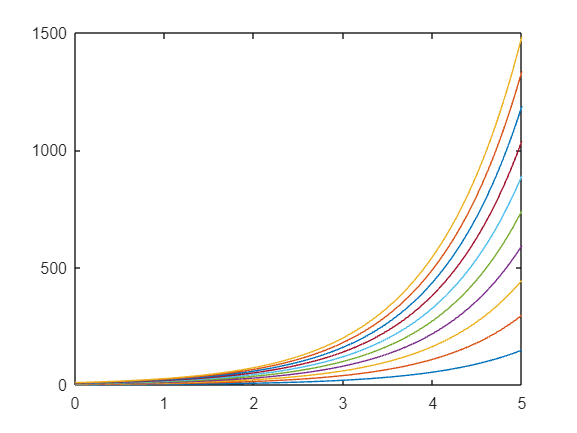

y = @(x,C) C*exp(x);
for C = 1:10
    plot(x, y(x,C))
    hold on
end 

## Slope Field example

In class, I will discuss on the board the slope field analysis for the ODE:


$$5\frac{dy}{dx} + 3y= \frac{1}{x}$$


which will be solved using an integrating factor. 